step 1: reading the input coordinate data from file ea_stats.mat

ds=fileDatastore('masterthesis/Percept-Pat ea_stats/ea_stats_data_in/', "FileExtensions", ".mat", ...
    "IncludeSubfolders", 1, "ReadFcn", @load)

ds =   FileDatastore with properties:

                       Files: {
                              ' ...\Percept-Pat ea_stats\ea_stats_data_in\PD066BW\ea_stats.mat';
                              ' ...\Percept-Pat ea_stats\ea_stats_data_in\PD070EM\ea_stats.mat';
                              ' ...\Percept-Pat ea_stats\ea_stats_data_in\PD071PH\ea_stats.mat'
                               ... and 33 more
                              }
                     Folders: {
                              ' ...\User\MATLAB Drive\masterthesis\Percept-Pat ea_stats\ea_stats_data_in'
                              }
                 UniformRead: 0
                    ReadMode: 'file'
                   BlockSize: Inf
                  PreviewFcn: @load
      SupportedOutputFormats: ["txt"    "csv"    "dat"    "asc"    "xlsx"    "xls"    "parquet"    "parq"    "png"    "jpg"    "jpeg"    "tif"    "tiff"    "w

% now, all ea_stats.mat files of the 36 patients are in the datastore

% load the 1st file:
load(string(ds.Files(1)))

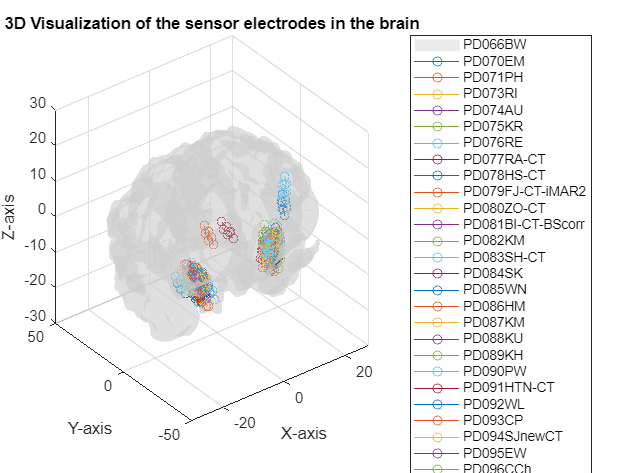

% load and superimpose a 3D model auf a brain (source: https://www.ameede.net/brain-b010144-file-obj-or-stl-free-download-3d-model-for-cnc-and-3d-printer/)
brain_mesh = stlread('brainmesh.stl');
faces = brain_mesh.ConnectivityList;
vertices = brain_mesh.Points;
% calculate the center of the brain image as new center of the coordinate
% system:
centroid = mean(vertices, 1);  % A 1x3 vector: [centroid_x, centroid_y, centroid_z]
figure;
% Efficiently subtract 100 from all x-values (first column of vertices)
vertices(:, 1) = vertices(:, 1) + 100;  % Modify x-values
vertices(:, 2) = vertices(:, 2) + 40;  % Modify y-values
vertices(:, 3) = vertices(:, 3) + 30;  % Modify z-values
trisurf(faces, vertices(:,1), vertices(:,2), vertices(:,3), ...
    'FaceAlpha', 0.4, 'EdgeColor', 'none', 'FaceColor', [0.8, 0.8, 0.8]);
hold on;
% Adjust axis limits based on the centroid, so that the origin is centered
legendArray = strings(0,1);

% axis_limits_padding_x = 100;  % Adjust padding as necessary to fit the brain and points well
% axis_limits_padding_y = 40;  % Adjust padding as necessary to fit the brain and points well
% axis_limits_padding_z = 30;  % Adjust padding as necessary to fit the brain and points well
% xlim([centroid(1) - axis_limits_padding, centroid(1) + axis_limits_padding]);
% ylim([centroid(2) - axis_limits_padding, centroid(2) + axis_limits_padding]);
% zlim([centroid(3) - axis_limits_padding, centroid(3) + axis_limits_padding]);
grid on;
% axis equal;

% loop over all ea_stats files of all 37 patients:
for fn = 1:length(ds.Files)
    load(string(ds.Files(fn)))
    % fetch the coordinates of the electrodes:
    coords_left = ea_stats.electrodes.coords_mm{1,1};
    coords_right = ea_stats.electrodes.coords_mm{1,2};
    % keep the name of the patient for the latter display of the legend:
    legendArray(fn) = string(ea_stats.patname(1));

    % calculate the euclidian distance:
    % distance_3_4 = norm(coords_right(3,:) - coords_right(4,:));
    % distances = pdist(coords_right, 'euclidean');

    % plot left electrode:
    x = coords_left(:, 1);
    y = coords_left(:, 2);
    z = coords_left(:, 3);
    % scatter3(x, y, z, 'filled');
    plot3(x,y,z, '-o')

    % plot right electrode:
    x = coords_right(:, 1);
    y = coords_right(:, 2);
    z = coords_right(:, 3);
    % scatter3(x, y, z, 'filled');
    plot3(x,y,z, '-o')
end

xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
legend(legendArray);
title('3D Visualization of the sensor electrodes in the brain')
hold off;

step 2: extracting the array with the coordinates:

step 3: cleanup and preprocessing the data:

step 4: building the model for training and prediction: